R1 = 787; R2 = 8713; L = 0.828; C1 = 50e-6; C2 = 80e-6;

amat = [-1/(R1*C1), 0, -1/C1;
        0, -1/(R2*C2), 1/C2;
        1/L, -1/L, 0];
bmat = [1/(R1*C1); 0; 0];
cmat = [0, 1, 0];
dmat = [0];

sys = ss(amat, bmat, cmat, dmat);

%step(sys)
%impulse(sys)
%bode(sys)

transfer = tf(sys)


transfer =
 
                 3.836e05
  ---------------------------------------
  s^3 + 26.85 s^2 + 3.929e04 s + 4.183e05
 
Continuous-time transfer function.




t = 0 : .001 : 0.7;
V = -0.915148.*exp(-10.69.*t)-0.001852.*exp(-8.11.*t).*cos(377.3.*t)-0.025969.*exp(-8.11.*t).*sin(377.3.*t)+0.917

V =     0.0000    0.0004    0.0024    0.0070    0.0150    0.0263    0.0408    0.0576    0.0756    0.0935    0.1101    0.1244    0.1355    0.1432    0.1477    0.1495    0.1497    0.1494    0.1497    0.1518    0.1565    0.1641    0.1747    0.1878    0.2026    0.2181    0.2332    0.2468    0.2580    0.2664    0.2718    0.2745    0.2752    0.2748    0.2743    0.2747    0.2770    0.2816    0.2889    0.2987    0.3105    0.3235    0.3367    0.3493    0.3602    0.3689    0.3751    0.3787    0.3801    0.3800


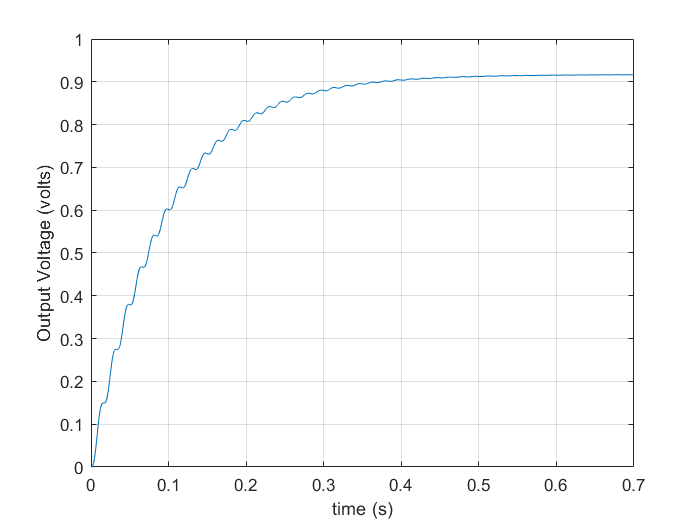

plot (t, V)
xlabel('time (s)')
ylabel('Output Voltage (volts)')
grid on


x = -15 : 0.01 : 15;
V1 = (-1/(2.*pi)).*(x.^2+1).^(-3/2)+(250/(4.*pi)).*(x.^2+25).^(-3/2)

V1 =     0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0055


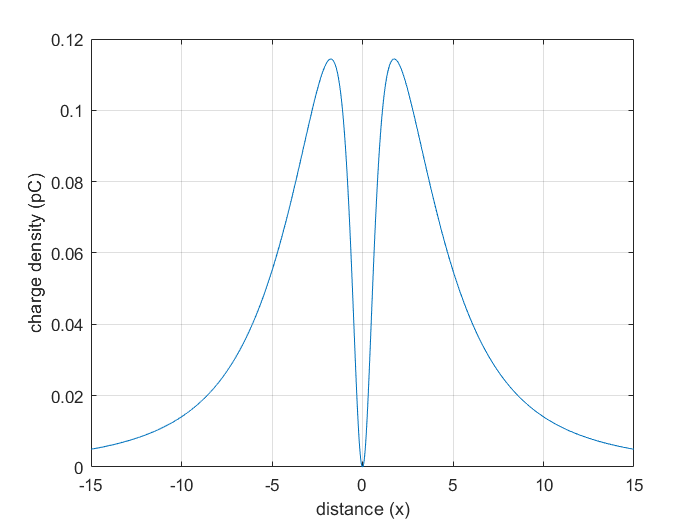

plot (x, V1)
xlabel('distance (x)')
ylabel('charge density (pC)')
grid on


syms x
denom = 0.013108.*x.^5+0.37071.*x.^4+713.194.*x.^3+11534.1.*x.^2+7779731.305.*x+82773500

$$denom = \frac{7556247541193275\,x^{5}}{576460752303423488}+\frac{37071\,x^{4}}{100000}+\frac{1568330191720153\,x^{3}}{2199023255552}+\frac{6340938532965581\,x^{2}}{549755813888}+\frac{1044177860207575\,x}{134217728}+82773500$$

F = factor(denom,x)

$$F = \left(\begin{array}{cc} \frac{1}{1801439850948198400000} & 23613273566228984375\,x^{5}+667811767145006628864\,x^{4}+1284776093057149337600000\,x^{3}+20777987384821615820800000\,x^{2}+14014718002496232488960000000\,x+149111481502460700262400000000 \end{array}\right)$$


denomvec = [1, 26.8476, 39287.75, 418303]

denomvec = 	1.0e+05 *

    0.0000    0.0003    0.3929    4.1830


roots(denomvec)

ans = 	1.0e+02 *

  -0.0808 + 1.9761i
  -0.0808 - 1.9761i
  -0.1069 + 0.0000i



numvec = [383650]

numvec = 383650

[r, p, k] = residue(numvec, denomvec)

r =   -4.9115 - 0.0651i
  -4.9115 + 0.0651i
   9.8229 + 0.0000i


p = 	1.0e+02 *

  -0.0808 + 1.9761i
  -0.0808 - 1.9761i
  -0.1069 + 0.0000i



k =

     []




t = 0 : .001 : 0.7;
h = 9.8229.*exp(-10.69.*t)+9.82.*exp(-8.08.*t).*cos(197.61.*t+179.24)

h =     0.1432    0.6256    1.4513    2.5790    3.9562    5.5218    7.2083    8.9448   10.6595   12.2826   13.7493   15.0016   15.9908   16.6795   17.0421   17.0664   16.7534   16.1172   15.1842   13.9918   12.5870   11.0243    9.3633    7.6666    5.9972    4.4162    2.9801    1.7390    0.7348   -0.0005   -0.4458   -0.5915   -0.4396   -0.0038    0.6918    1.6132    2.7184    3.9589    5.2818    6.6319    7.9539    9.1944   10.3042   11.2398   11.9653   12.4533   12.6864   12.6571   12.3683   11.8328


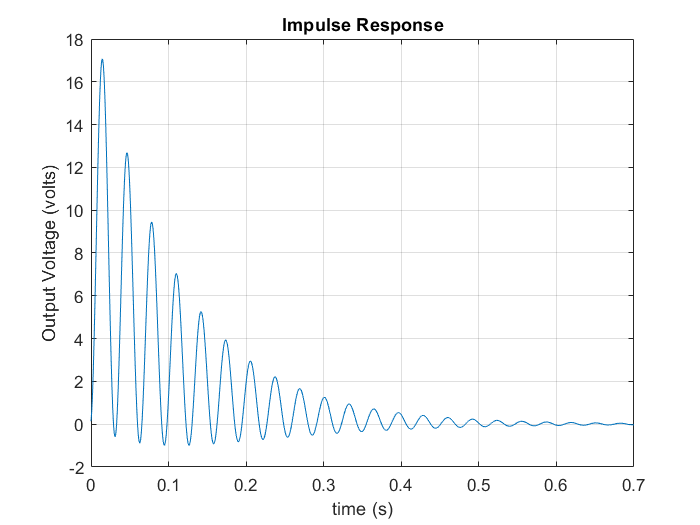

plot (t, h)
xlabel('time (s)')
ylabel('Output Voltage (volts)')
title('Impulse Response')
grid on


denomvecstep = [1, 26.8476, 39287.75, 418303, 0]

denomvecstep = 	1.0e+05 *

    0.0000    0.0003    0.3929    4.1830         0


roots(denomvec)

ans = 	1.0e+02 *

  -0.0808 + 1.9761i
  -0.0808 - 1.9761i
  -0.1069 + 0.0000i



numvecstep = [383650]

numvecstep = 383650

[ro, po, ko] = residue(numvecstep, denomvecstep)

ro =    0.0007 + 0.0248i
   0.0007 - 0.0248i
  -0.9185 + 0.0000i
   0.9172 + 0.0000i


po = 	1.0e+02 *

  -0.0808 + 1.9761i
  -0.0808 - 1.9761i
  -0.1069 + 0.0000i
   0.0000 + 0.0000i



ko =

     []





t = 0 : .001 : 0.7;
h = -0.9185.*exp(-10.69.*t)+0.055618.*exp(-8.08.*t).*cos(197.61.*t+1.54562)+0.9172

h =     0.0001   -0.0010   -0.0017   -0.0015   -0.0002    0.0027    0.0072    0.0135    0.0219    0.0321    0.0442    0.0580    0.0732    0.0897    0.1070    0.1249    0.1429    0.1606    0.1778    0.1940    0.2090    0.2224    0.2343    0.2442    0.2524    0.2586    0.2631    0.2659    0.2673    0.2676    0.2669    0.2656    0.2641    0.2627    0.2617    0.2614    0.2621    0.2640    0.2672    0.2719    0.2780    0.2857    0.2948    0.3052    0.3166    0.3290    0.3420    0.3553    0.3687    0.3819


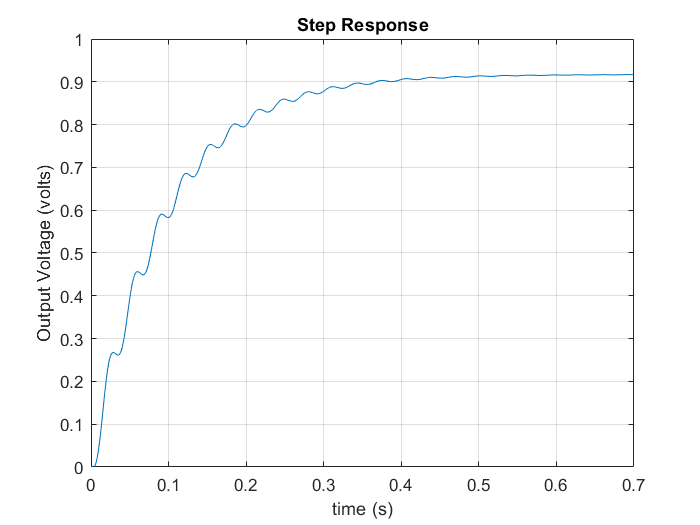

plot (t, h)
axis([0 0.7 0 1])
xlabel('time (s)')
ylabel('Output Voltage (volts)')
title('Step Response')
grid on

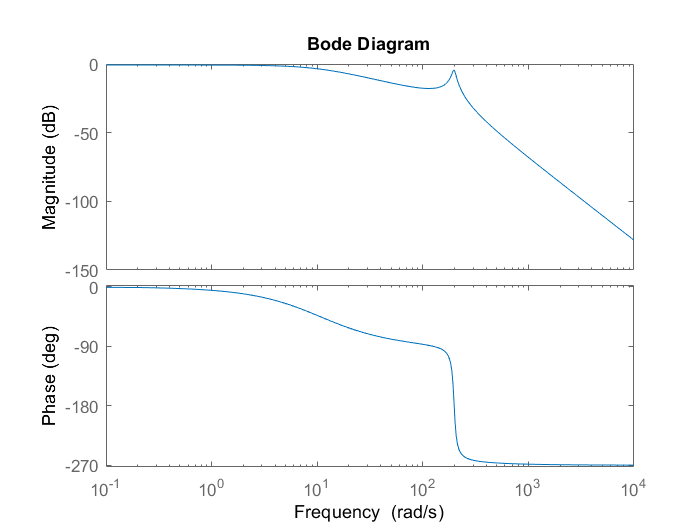


sys2 = tf(numvec,denomvec);
bode(sys2);


t = 0 : .001 : 0.7;
V = 0.918-0.9189.*exp(-10.69.*t)-0.002029.*exp(-8.08.*t).*cos(197.61.*t+3.12)+0.04961.*exp(-8.08.*t).*sin(197.61.*t+3.12)

V =     0.0022    0.0022    0.0026    0.0036    0.0056    0.0088    0.0135    0.0199    0.0279    0.0377    0.0491    0.0621    0.0764    0.0918    0.1080    0.1248    0.1417    0.1585    0.1748    0.1903    0.2047    0.2178    0.2295    0.2395    0.2479    0.2546    0.2597    0.2633    0.2655    0.2667    0.2670    0.2667    0.2662    0.2656    0.2654    0.2657    0.2668    0.2690    0.2723    0.2769    0.2829    0.2901    0.2987    0.3084    0.3191    0.3307    0.3428    0.3553    0.3679    0.3803


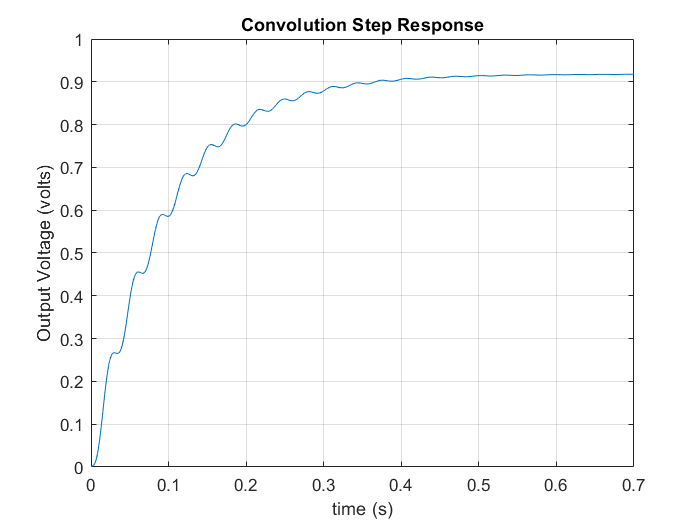

plot (t, V)
xlabel('time (s)')
ylabel('Output Voltage (volts)')
title('Convolution Step Response')
grid on


t = 0 : .001: 0.7;
h = 9.8229.*exp(-10.69.*t)+9.82.*exp(-8.08.*t).*cos(197.61.*t+179.24)

h =     0.1432    0.6256    1.4513    2.5790    3.9562    5.5218    7.2083    8.9448   10.6595   12.2826   13.7493   15.0016   15.9908   16.6795   17.0421   17.0664   16.7534   16.1172   15.1842   13.9918   12.5870   11.0243    9.3633    7.6666    5.9972    4.4162    2.9801    1.7390    0.7348   -0.0005   -0.4458   -0.5915   -0.4396   -0.0038    0.6918    1.6132    2.7184    3.9589    5.2818    6.6319    7.9539    9.1944   10.3042   11.2398   11.9653   12.4533   12.6864   12.6571   12.3683   11.8328


u=ones(1,701)

u =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


rt=conv(h,u).*0.001

rt =     0.0001    0.0008    0.0022    0.0048    0.0088    0.0143    0.0215    0.0304    0.0411    0.0534    0.0671    0.0821    0.0981    0.1148    0.1318    0.1489    0.1657    0.1818    0.1970    0.2109    0.2235    0.2346    0.2439    0.2516    0.2576    0.2620    0.2650    0.2667    0.2675    0.2675    0.2670    0.2664    0.2660    0.2660    0.2667    0.2683    0.2710    0.2750    0.2802    0.2869    0.2948    0.3040    0.3143    0.3256    0.3375    0.3500    0.3627    0.3753    0.3877    0.3995


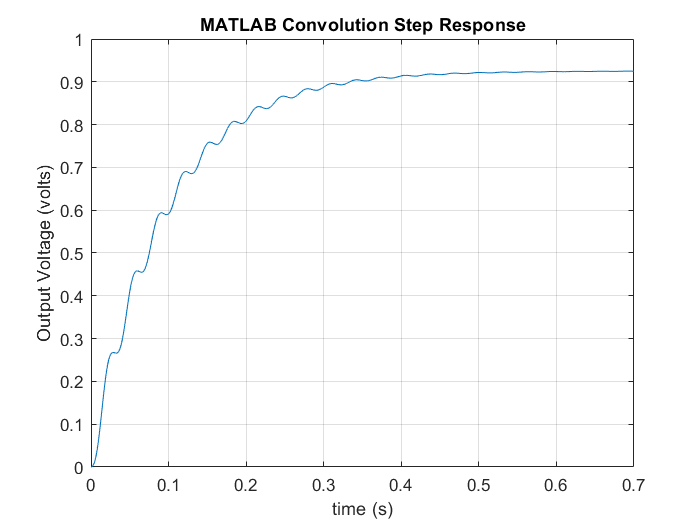

plot(t, rt(1:length(t)))
axis([0 0.7 0 1])
xlabel('time (s)')
ylabel('Output Voltage (volts)')
title('MATLAB Convolution Step Response')
grid on


x = 0 : 0.0001 : 0.035;
V1 = 1+0.5.*pi.*sin(pi.*120.*x)+2.*(-1/3.*cos(2.*pi.*120.*x)-1/15.*cos(4.*pi.*120.*x)-1/35.*cos(6.*pi.*120.*x)-1/65.*cos(8.*pi.*120.*x)-1/99.*cos(10.*x)-1/143.*cos(12.*pi.*120.*x)-1/195.*cos(14.*pi.*120.*x)-1/255.*cos(16.*pi.*120.*x)-1/323.*cos(18.*pi.*120.*x)-1/399.*cos(20.*pi.*120.*x))

V1 =     0.0486    0.1210    0.2169    0.3290    0.4482    0.5666    0.6798    0.7879    0.8938    1.0013    1.1132    1.2295    1.3478    1.4647    1.5767    1.6824    1.7817    1.8760    1.9665    2.0539    2.1376    2.2172    2.2921    2.3631    2.4316    2.4994    2.5677    2.6366    2.7047    2.7700    2.8302    2.8841    2.9314    2.9725    3.0077    3.0373    3.0612    3.0788    3.0903    3.0966    3.0992    3.0999    3.0999    3.0995    3.0978    3.0929    3.0833    3.0677    3.0460    3.0182


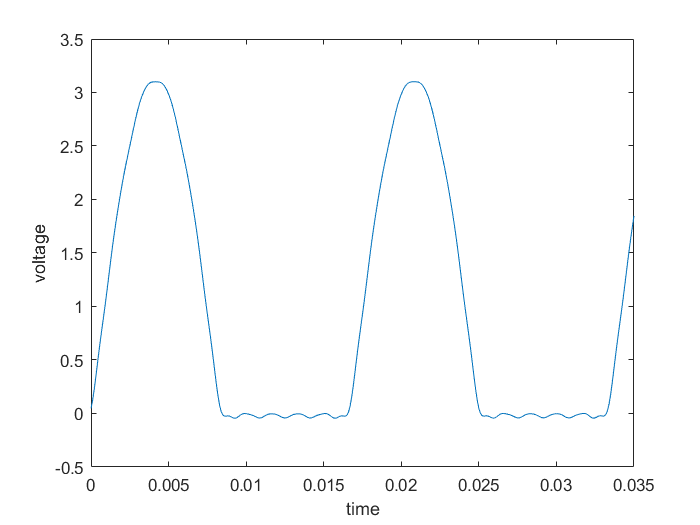

plot (x, V1)
xlabel('time')
ylabel('voltage')

%hold on

x = 0 : 0.0001 : 0.035;
V1 = 0.46865.*(1+0.5.*pi.*sin(pi.*120.*x-1.08303)+2.*(-1/3.*cos(2.*pi.*120.*x-1.08303)-1/15.*cos(4.*pi.*120.*x-1.08303)-1/35.*cos(6.*pi.*120.*x-1.08303)-1/65.*cos(8.*pi.*120.*x-1.08303)-1/99.*cos(10.*pi.*120.*x-1.08303)-1/143.*cos(12.*pi.*120.*x-1.08303)-1/195.*cos(14.*pi.*120.*x-1.08303)-1/255.*cos(16.*pi.*120.*x-1.08303)-1/323.*cos(18.*pi.*120.*x-1.08303)-1/399.*cos(20.*pi.*120.*x-1.08303)))

V1 =    -0.3906   -0.4247   -0.4476   -0.4577   -0.4562   -0.4460   -0.4308   -0.4135   -0.3954   -0.3763   -0.3552   -0.3308   -0.3027   -0.2713   -0.2378   -0.2031   -0.1681   -0.1325   -0.0957   -0.0571   -0.0165    0.0259    0.0693    0.1130    0.1565    0.1999    0.2436    0.2882    0.3338    0.3802    0.4268    0.4729    0.5183    0.5631    0.6076    0.6522    0.6971    0.7420    0.7864    0.8297    0.8716    0.9122    0.9519    0.9909    1.0295    1.0673    1.1038    1.1386    1.1713    1.2020


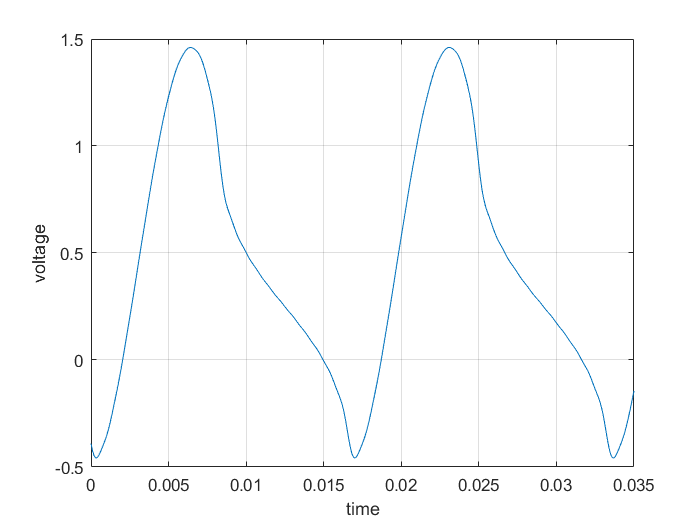

plot (x, V1)
xlabel('time')
ylabel('voltage')
grid on


clear()

N = 20;
t = 0 : 0.0001 : 0.03;
w0 = 120*pi;

Vm = 1;
v = Vm/pi;
for n=1:N
    if n==1
        v = v+sin(w0*t)/2;
    elseif mod(n,2)==0
        v = v+2*cos(n*w0*t)/pi/(1-n^2);
    end
end

vf = Vm/pi;
for n1 = 1:N
    shift = 1/sqrt(1+(w0*n1/200)^2);
    phase = -atan(w0*n1/200);
    if n1==1
        vf = vf+shift*sin(w0*t + phase)/2;
    elseif mod(n1,2)==0
        vf = vf+2*shift*cos(n1*w0*t+phase)/pi/(1-n1^2);
    end
end

plot(t, v, 'Linewidth', 2)
hold on
plot(t,vf)
grid on

syms w;
h(w) = 1/(((1i*w)^2/200^2+0.765i*w/200+1)*((1i*w^2)/200^2+1.848i*w/200+1))

$$h(w) = \frac{1}{\left(\frac{w^{2}\,\mathrm{i}}{40000}+\frac{231\,w\,\mathrm{i}}{25000}+1\right)\,\left(-\frac{w^{2}}{40000}+\frac{153\,w\,\mathrm{i}}{40000}+1\right)}$$

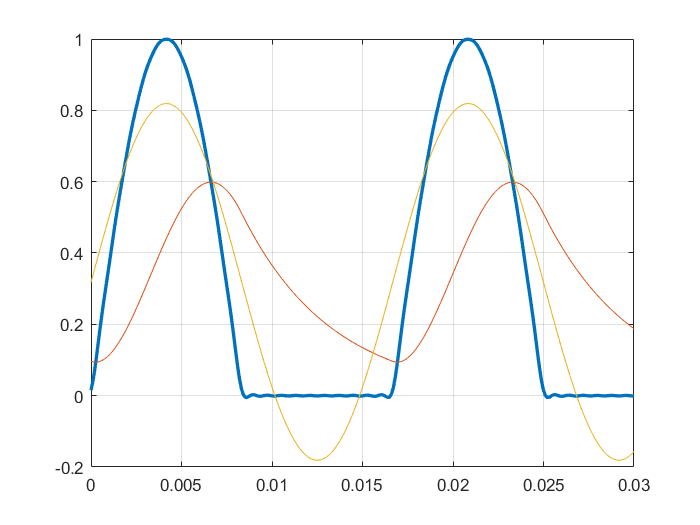


vb = Vm/pi;
for n1 = 1:N
    if n1==1
        vb = vb+abs(h(0))*sin(w0*t + angle(h(0)))/2;
    elseif mod(n1,2)==0
        vb = vb+2*abs(h(w0*n1))*cos(n1*w0*t+angle(h(0)))/pi/(1-n1^2);
    end
end

%plot(t, v, 'Linewidth', 2)
%hold on
plot(t,vb)
grid on